# **複数試行を処理　**

分析部分を適切に関数化し、for loop を用いて処理することで、複数試行を一度に分析する

注意点

・想定通りに分析できているとは限らないので、必ず、全試行の図を目視して、分析できていることを確認すること

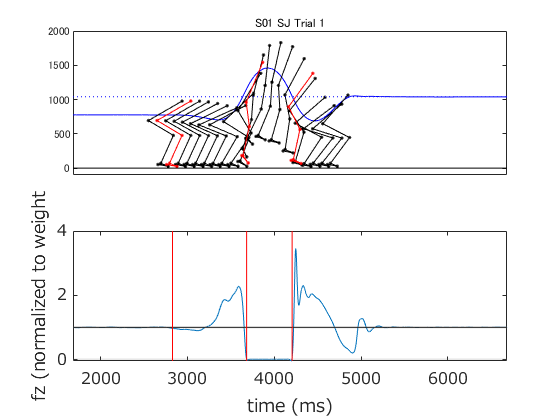

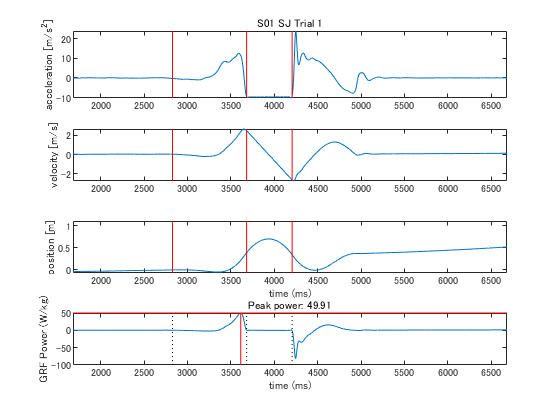

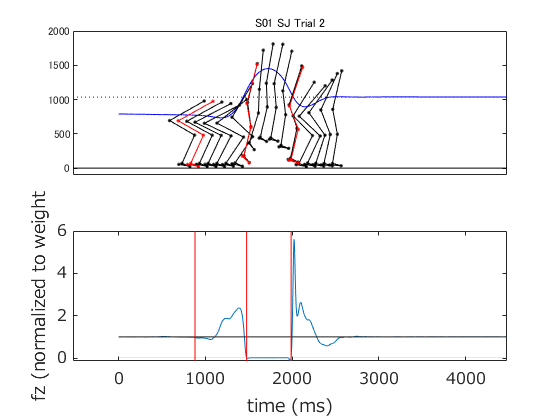

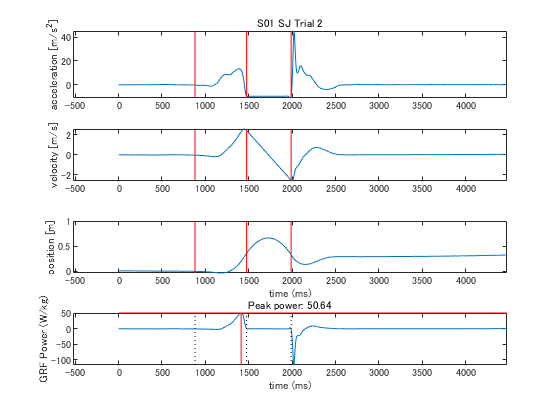

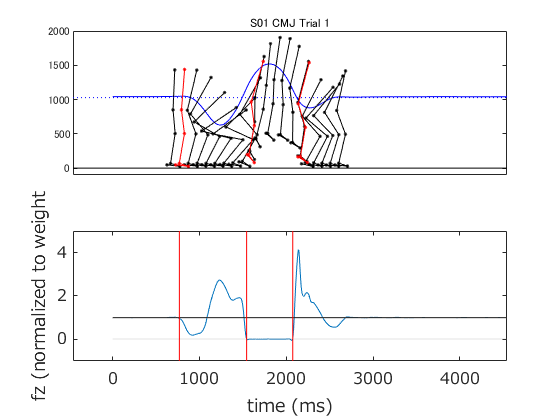

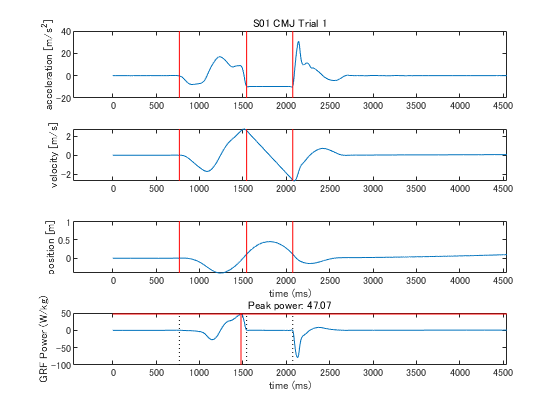

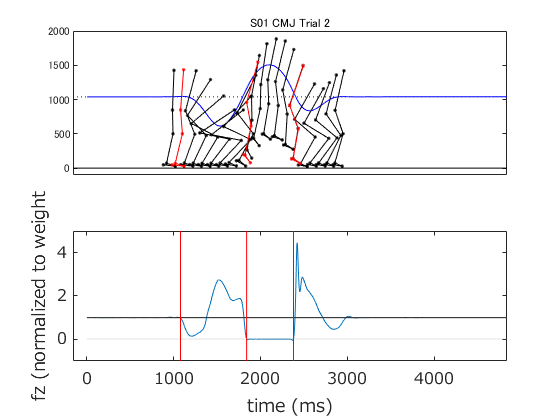

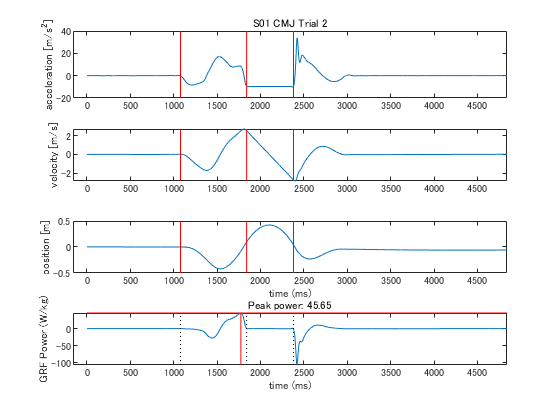

clear
close all
clc


% *** 実験実習で測定計測したデータ を load***
iSubject = 1 ; % ←　被験者番号を指定する
fileName = sprintf('Data_S%02d', iSubject) ; 
load(fileName) ;

% 分析する条件名
ConditionNameArray = {'SJ', 'CMJ', 'FA'} ; % squat jump, counter movement jump, fatigue

% イベント検出用閾値
Prm.Alpha = 0.03 ; % ジャンプ動作開始 (/weight)
Prm.Beta = 0.03 ; % 着地と離地
Prm.Win = 50 ; % ジャンプ動作開始・着地・離地分析の際の、時間ウィンドウ (ms)

% 分析スクリプト
ii = 0 ;
nCondition = length(ConditionNameArray) ;
for iCondition = 1:nCondition
    conditionName = ConditionNameArray{iCondition} ;
    
    for iTrial = 1:2
        Data = DataStruct.(conditionName)(iTrial) ;
        
        
        [Result, ax1, ax2] = analyze(Data, Prm) ;
        
        titleText = [sprintf('S%02d ', iSubject), conditionName, sprintf(' Trial %d', iTrial) ];
        axes(ax1(1)) ;
        title(titleText)
        axes(ax2(1)) ;
        title(titleText)
                
        ii = ii+1 ;
        ResultArray(ii).ID = iSubject ;
        ResultArray(ii).Condition = conditionName ;
        ResultArray(ii).Trial = iTrial ;
        ResultArray(ii).JumpHeightFP = Result.JumpHeightFP ;
        ResultArray(ii).JumpHeightMarkers = Result.JumpHeightMarkers ;
        ResultArray(ii).PeakPower = Result.PeakPower ;
        ResultArray(ii).AvgPower = Result.AvgPower ;
        
    end
end


T = struct2table(ResultArray) ;

fileName = sprintf('ResultTable_S%02d.csv', iSubject) ;
writetable(T, fileName)



function [Results, ax1, ax2] = analyze(Data, Prm)

    grfs = Data.Forces ;
    fz = grfs(:,3) + grfs(:,6) ;
    Markers = Data.Markers ;
    
    % イベント検出
    JumpEvent = detectJumpEvent(fz, Prm) ;
    
    % 重心計算
    Segments = calculateCoM(Markers) ;
    
    % 作図１
    figure ;
    ax1(1) = subplot(2,1,1) ;
    figStickPicture(Markers, Segments, JumpEvent)
    ax1(2) = subplot(2,1,2) ;
    figJumpEvent(fz, Prm, JumpEvent) ;
    
    % 床反力パワー
    [GRFPower, PowerTimeSeries] = calculatePower(fz, JumpEvent) ;
    ax2 = figGRFPower(GRFPower, PowerTimeSeries, JumpEvent) ;
    
    % 跳躍高
    % 離地時の速度　→　跳躍高
    velAtTakeOff = PowerTimeSeries.Vel(JumpEvent.TakeOff) ;
    jumpHeightFP = (1/2) * velAtTakeOff^2 / gravity ;
    % マーカー　→　重心
    jumpHeightMarkers = ( max(Segments.CoM(:,3)) - mean(Segments.CoM(end-1000:end,3)) )/1000 ;
    
    % Result
    Results.JumpHeightFP = jumpHeightFP ;
    Results.JumpHeightMarkers = jumpHeightMarkers ;
    Results.PeakPower = GRFPower.PeakPower ;
    Results.AvgPower = GRFPower.AvgPower ;
    
    
end


function Segments = calculateCoM(Markers)

    Segments.HAT   = 0.374 * Markers.Gt    + 0.678 * Markers.Shoulder ; 
    Segments.Thigh = 0.567 * Markers.Gt    + 0.433 * Markers.Knee ;  
    Segments.Leg   = 0.567 * Markers.Knee  + 0.433 * Markers.Ankle ; 
    Segments.Foot  = 0.5   * Markers.Ankle + 0.5   * Markers.MP5 ; 
    
    Segments.CoM = Segments.HAT * 0.678 + Segments.Thigh * 0.1 * 2 + ...
                   Segments.Leg * 0.0465 * 2 + Segments.Foot * 0.0145 * 2 ;

end


function JumpEvent = detectJumpEvent(fz, Prm)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    baseFz = 1 ;

    tOnsetJump = 0 ; % 変数の初期化
    for ii = 2:n-win
        % 条件１　ジャンプ開始時刻の直前の fz は、ベースライン±αの範囲内にある
        criteria1 = fz(ii-1) < baseFz*(1+alpha) && fz(ii-1) > baseFz*(1-alpha) ;
    
        % 条件２　ジャンプ開始時刻から win (ms)間、 fz は、ベースライン±α の範囲外にある
        criteria2 = all(fz(ii:ii+win) >= baseFz*(1+alpha)) || all(fz(ii:ii+win) <= baseFz*(1-alpha)) ;
    
        if criteria1 && criteria2 % 上記の2条件を同時に満たす
            tOnsetJump = ii ;
            break % 1回検出したら、ループを抜ける
        end
        
    end
    
    
    % takeoff
    tTakeOff = 0 ;
    for ii = 2:n-win
        if all( fz(ii:ii+win) < beta )
            tTakeOff = ii ;
            break
        end
    end
    
    % landing
    tLanding = 0 ;
    for ii = tTakeOff:n-win
        if all( fz(ii:ii+win) > beta )
            tLanding = ii ;
            break
        end
    end
    
    % output
    JumpEvent.OnsetJump = tOnsetJump ;
    JumpEvent.TakeOff = tTakeOff ;
    JumpEvent.Landing = tLanding ;
    
end

function figStickPicture(Markers, Segments, JumpEvent)
    
    Markers2 = Markers ;
    plot(Segments.CoM(:,3), 'b-') ; hold on
    for iFrame = [JumpEvent.OnsetJump-100 : 100 : JumpEvent.Landing+500] 
        MarkerNames = fieldnames(Markers) ;
        for iMarker = 1:length(MarkerNames)
            Markers2.(MarkerNames{iMarker})(:,2) = Markers.(MarkerNames{iMarker})(:,2) - 150 + iFrame ;
        end
        stickPicture(Markers2, MarkerNames, iFrame, 'yz', 'k.-') ;
    end
    for iFrame = [JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing] 
        MarkerNames = fieldnames(Markers) ;
        for iMarker = 1:length(MarkerNames)
            Markers2.(MarkerNames{iMarker})(:,2) = Markers.(MarkerNames{iMarker})(:,2) - 150 + iFrame ;
        end
        stickPicture(Markers2, MarkerNames, iFrame, 'yz', 'r.-') ;
    end
    

    xlim = [-2000,3000] ;
    set(gca, 'xlim', xlim+JumpEvent.TakeOff, 'ylim', [-100,2000])
    set(gca, 'xtick', [])
    lineplot(0,'h','k') ;
    lineplot(mean(Segments.CoM(end-1000:end,3)),'h','b:') ;
    
end

function figJumpEvent(fz, Prm, JumpEvent)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    baseFz = 1 ;
    
    % イベント時刻
    tOnsetJump = JumpEvent.OnsetJump ;
    tTakeOff = JumpEvent.TakeOff ;
    tLanding = JumpEvent.Landing ;
    
    % 図の作成
    plot(fz) ; % イベント検出に用いた時系列データ 
    
    % イベント検出に用いた閾値を図示　（※　進矢の自作関数を使っています
    lineplot(1, 'h', 'k') ; 
    arealine([baseFz-alpha, baseFz+alpha], 'h') ; 
    arealine([0, beta], 'h') ;
    
    % 検出されたイベントを図示
    lineplot([tOnsetJump, tTakeOff, tLanding], 'v', 'r') ;
    
    % 表示範囲を設定
    xlim = [-2000,3000] ;
    set(gca, 'xlim', xlim+tTakeOff)
    
    % 凡例等
    xlabel('time (ms)')
    ylabel('fz (normalized to weight')
%     titleText = { sprintf('Onset of jump: %d', tOnsetJump) ;... % sprintf: 数値を文字列にフォーマットするときに用いる
%                   sprintf('Take-off: %d', tTakeOff) ;...
%                   sprintf('Landing: %d', tLanding) } ;
%     title(titleText)
    set(gca, 'fontname', 'meiryo', 'fontsize', 12)

end


function [GRFPower, PowerTimeSeries] = calculatePower(fz, JumpEvent)
    
%     fz = fz / mean(fz(1:1000)) ;
    
    % 数値積分
    z2Dot = (fz-1) * gravity ; % ここの fz が、体重で正規化された値であることに注意
    zDot = cumtrapz(z2Dot) * 0.001 ; % cumtrapz: 累積台形積分を計算する関数
    z = cumtrapz(zDot) * 0.001 ;
    z = z - z(JumpEvent.OnsetJump) ; % onset of jump motion の時刻における位置を基準とする
    
    PowerTimeSeries.Acc = z2Dot ;
    PowerTimeSeries.Vel = zDot ;
    PowerTimeSeries.Z = z ;
        
    % power
    grfPower = (fz*gravity) .* zDot ; % [N/bodyMass * m/s] = [J/s /bodyMass] = [W/bodyMass]
    PowerTimeSeries.GRFPower = grfPower ;
    
    avgPower = mean(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % 動作開始から離地までの平均パワー
    [peakPower, tPeakPower] = max(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % [W / kg] ### weight = m [kg] * g [m/s2]
    tPeakPower = tPeakPower + JumpEvent.OnsetJump - 1 ;
    
    GRFPower.AvgPower = avgPower ;
    GRFPower.PeakPower = peakPower ;
    GRFPower.tPeakPower = tPeakPower ;
    
    
end


function ax = figGRFPower(GRFPower, PowerTimeSeries, JumpEvent)
    xlim = [-2000,3000] ;
    
    figure
    ax(1) = subplot(4,1,1) ;
    plot(PowerTimeSeries.Acc)
    ylabel('acceleration [m/s^2]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    
    ax(2) = subplot(4,1,2) ;
    plot(PowerTimeSeries.Vel)
    ylabel('velocity [m/s]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    
    ax(3) = subplot(4,1,3) ;
    plot(PowerTimeSeries.Z)
    ylabel('position [m]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    xlabel('time (ms)')
    
    ax(4) = subplot(4,1,4) ;
    plot(PowerTimeSeries.GRFPower) ;
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'k:') ;
    lineplot(GRFPower.tPeakPower, 'v', 'r') ;
    lineplot(GRFPower.PeakPower, 'h', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    ylabel('GRF Power (W/kg)')
    xlabel('time (ms)')
    title(sprintf('Peak power: %0.2f', GRFPower.PeakPower))



end

